# Lesson II.3:   Characteristic Polynomials, Eigenvalues and Diagonalization of 2x2 Matrices (F24)

As we learn in later lessons, the eigenvalues of a square matrix can be valuable information for its analysis.     The eigenvalues are the roots of the characteristic polynomial of the matrix.  Hence, a considerable part of this lesson is review of the basic ideas surrounding finding the roots of polynomials.    This is a hard problem.   So hard that for numerical matrices MATLAB generally uses iterative methods that only produce approximations of the roots.   Happily, those approximations are generally extremely accurate and suitable for use in most applications.    Our focus, however, will be on exact answers as this seems to be the basis on which most students are best able to develop an understanding of eigenvalues and their use.

**Eigenvectors:   motivation for the study of characteristic polynomials.     **An eigenvector for an $n\times n$matrix $A$ is a nonzero vector ${\bf x}\in{\mathbb R}^n$ such that ${\bf x} $ and $A{\bf x}$ point along the same line.   That is, there is a scalar $\lambda$, called an ***eigenvalue***, such that $A{\bf x}=\lambda{\bf x}$.   From this equation, the characteristic equation satisfied by the eigenvalue is easily derived:

                     
$$A{\bf x}~=~\lambda{\bf x}\qquad\qquad ({\bf x}\ne{\bf 0})$$



$$\qquad\Leftrightarrow\qquad$$

$$A{\bf x}=\lambda I {\bf x}\qquad\qquad({\bf x}\ne{\bf 0})$$



$$\qquad\Leftrightarrow\qquad$$

$$(A-\lambda I){\bf x}={\bf 0}\qquad({\bf  x}\ne{\bf 0})$$


$\qquad\Leftrightarrow\qquad$$\text{det}(A-\lambda I)=0$.

This equation for the eigenvalues of a square matrix is the subject of this lesson.

**Characteristic polynomial and eigenvalues.  **The ***characteristic polynomial*** of an $n\times n$ matrix $A$ is 

        (II.3.1)        $p_A(\lambda)~=~\det(A-\lambda I).$

The characteristic polynomial $p_A(\lambda)$ is a polynomial of degree $n$ (i.e., the highest power of $\lambda$ is $n$).   It is important to remember that because the definition requires taking a determinant that the concept of characteristic polynomial (and later the concept of eigenvalues) only applies to square matrices.   For the general $2\times 2$ matrix, the characteristic polynomial is easily found:

        (II.3.2a)        $p_A(\lambda)=\det\left(\left[\matrix{a&b\cr c&d}\right]~-~\lambda \left[\matrix{1&0\cr 0 & 1 }\right]\right)=\det \left[\matrix{a-\lambda & b\cr c & d-\lambda}\right]=(a-\lambda)(d-\lambda)-bc~$

                          
$$\qquad\quad=~\lambda^2~-~(a+d)\lambda ~+~ad-bc$$


The constant term $ad-bc$ is readily recognized as the determinant of the matrix which is expected as obviously $P_A(0)=\text{det}(A-0I)=|A|$ for any square matrix.  The coefficient of $\lambda$ is the negative of the sum of the diagonal elements of the matrix.   In general, the sum of the elements of the main diagonal of a square matrix is known as the ***trace*** of the matrix.   Hence, for a $2\times 2$ matrix $A$, the characteristic polynomial can be rewritten as

        (II.3.2b)        $p_A(\lambda)~=~\lambda^2~-~\text{tr}(A)\lambda~+~\det(A)$

where $\text{tr}(A)$ denotes the trace of $A$.    For larger matrices, the computation of the characteristic polynomial can be considerably more complicated.   It is helpful to first explore the $2\times 2$ case before launching into more general cases.   

**The eigenvalues of **$2\times 2$ **matrices.**    Since (II.3.2b) defines a quadratic polynomial, the quadratic formula gives the roots (eigenvalues):

        (II.3.3)        $\lambda_\pm=\frac12\bigg(\text{tr}(A)\pm\sqrt{\text{tr}^2(A)-4\det(A)}\bigg)$.

Some examples:

    (II.3.4a)    $A=\left[ \matrix{ 1 & 1 \cr 1 & 0 } \right]\quad\Rightarrow\quad\text{tr}(A)=1,\quad\det(A)=-1\quad\Rightarrow\quad \lambda_\pm=\frac{1\pm\sqrt{1^2-4(-1)} }{2} ~=~\frac{1\pm\sqrt{5}}{2}$

    (II.3.4b)    $A=\left[ \matrix{ 3 & 2 \cr -2 & 3 } \right]\quad\Rightarrow\quad\text{tr}(A)=6,\quad\det(A)=13
\quad\Rightarrow\quad 
\lambda_\pm=\frac{6\pm\sqrt{36-4(13)} }{2} ~=~3\pm 2i$

    (II.3.4c)    $A=\left[ \matrix{ 3 & 2 \cr 0 & 3 } \right]\quad\Rightarrow\quad\text{tr}(A)=6,\quad\det(A)=9
\quad\Rightarrow\quad 
\lambda_\pm=\frac{6\pm\sqrt{36-4(9)} }{2} ~=~3$

    (II.3.4d)    $A=\left[ \matrix{ 1 & 3+2i \cr 3-2i & 1 } \right]\quad\Rightarrow\quad\text{tr}(A)=2,\quad\det(A)=-12\quad\Rightarrow\quad \lambda_\pm=\frac{2\pm\sqrt{2^2-4(-12)} }{2} ~=~1\pm\sqrt{13}$

An obvious, but important, observations is that the characteristic polynomials of $2\times 2$.matrices generally have two distinct roots (two eigenvalues) but will have only one when $\text{tr}^2(A)=4\det(A)$.   The roots may be real or complex.  When the matrix is real, the complex roots will be a complex conjugate pair ($\lambda_+=a+bi$ and $\lambda_-=a-bi$).   The eigenvalues of a complex matrix, as in (II.3.4d), may be real; in fact, we will see that the eigenvalues of a Hermitian symmetric matrix ($A^H=A$) are always real.    

The set of all the eigenvalues of a matrix $A\;$is called the ***spectrum*** of the matrix and is denoted $\sigma(A)$.   From (II.3.4abcd) we have

                
$$\sigma \left( \left[\matrix{ 1& 1\cr 1 & 0}\right]\right)=\left\{ \frac{1+\sqrt{5}}{2},~ \frac{1-\sqrt{5}}{2}\right\},\quad
\sigma \left( \left[\matrix{ 3& 2\cr -2 & 3}\right]\right)=\left\{ 3+2i,~3-2i\right \},\quad
$$


                
$$\sigma \left( \left[\matrix{ 3& 2\cr 0 & 3}\right]\right)=\left\{ 3\right\},\quad
\sigma \left( \left[\matrix{ 1& 3+2i\cr 3-2i & 1}\right]\right)=\left\{ 1+\sqrt{13},1-\sqrt{13}\right\}.$$


In the examples above, we can count the distinct eigenvalues of the matrix which anticipate a general result for $n\times n $ matrices:   an $n\times n$ matrix will always have a spectrum containing from 1 to $n$ eigenvalues.    There is however a slightly different perspective on the counting of eigenvalues which is associated with the factorization of the characteristic polynomial into linear factors (always possible according to the Fundamental Theorem of Algebra).    Consider this factorization for the examples above:

    (II.3.5a)    $A=\left[ \matrix{ 1 & 1 \cr 1 & 0 } \right]\quad\Rightarrow\quad p_A(\lambda)=\lambda^2-\lambda-1~=~\left(\lambda-\frac{1+\sqrt{5}}{2}\right)\left(\lambda-\frac{1-\sqrt{5}}{2}\right)
$

    (II.3.5b)    $A=\left[ \matrix{ 3 & 2 \cr -2 & 3 } \right]\quad\Rightarrow\quad p_A(\lambda)=\lambda^2-6\lambda+13~=~\big(\lambda-(3+2i)\big)\big(\lambda-(3-2i)\big)$

    (II.3.5c)    $A=\left[ \matrix{ 3 & 2 \cr 0 & 3 } \right]\quad\Rightarrow\quad p_A(\lambda)=\lambda^2-6\lambda-9~=~(\lambda-3)(\lambda-3)$

    (II.3.5d)    $A=\left[ \matrix{ 1 & 3+2i \cr 3-2i & 1 } \right]\quad\Rightarrow\quad p_A(\lambda)=\lambda^2-2\lambda-12~=~\big(\lambda-(1+\sqrt{13})\big)\big(\lambda-(1-\sqrt{13})\big)$

The more subtle counting of the eigenvalues associates to each eigenvalue $\lambda_\ell$ another number, the ***multiplicity*** of the eigenvalue (often denoted $\mu_\ell$), which is the number of factors of the characteristic polynomial in which the eigenvalue appears.    For each of the examples above, except (II.3.5.c), there are two eigenvalues in the spectrum each with a multiplicity of 1.    For (II.3.4.c) there is one eigenvalue in the spectrum that has a multiplicity of 2.    Hence, for all the examples above, the sum of the multiplicities of all the eigenvalues is equal to 2.    This anticipates the general result (based on the Fundamental Theorem of Algebra) that an $n\times n$ matrix may have from 1 to $n$ distinct eigenvalues but the sum of the multiplicities of the eigenvalues is nonetheless always $n$.   In symbols we can write

        (II.3.5)    $n=\sum_{\ell=1}^{|\sigma(A)|}\mu_\ell$

where $|\sigma(A)|$ is the number of elements in the set $\sigma(A)$.

It turns out that in most applications, the eigenvalues are used according to their multiplicities.   Hence, maintaining an awareness of the multiplicities of the eigenvalues of a matrix is important.    It is moreover often a useful check to verify that the multiplicities of the eigenvalues as found in a calculation indeed sum to $n$.

Focusing on the case $n=2$, we see that every $2\times 2$ matrix maybe thought of as having exactly 2 eigenvalues $\lambda_1~\text{and}~\lambda_2$ but where we allow the possibility that $\lambda_1=\lambda_2$ (i.e., the count of 2 depends on counting by multiplicity).    With the two eigenvalues, 

        (II.3.6)        $p_A(\lambda)~=~(\lambda-\lambda_1)(\lambda-\lambda_2)~=~\lambda^2-(\lambda_1+\lambda_2)\lambda~+~\lambda_1\lambda_2$   

and comparing with (II.3.2a) and (II.3.2b) 

        (II.3.7)        $\matrix{
\text{tr}(A) &=& A_{11}~+~A_{22}&=&\lambda_1~+~\lambda_2\cr
\det(A)&=& A_{11}A_{22}-A_{12}A_{21}&=&\lambda_1\lambda_2
}$.

This anticipates the general result for $n\times n$ matrices that when each eigenvalue is repeated according to its multiplicity:

- the trace (sum of the diagonal elements) is equal to the sum of the $n$ eigenvalues, and

- the determinant is equal to the product of the $n$ eigenvalues.

By definition, $\lambda\in\sigma(A)~\Rightarrow~p_A(\lambda)=0$.    This obvious result has an interesting extension to matrix equations known as the Cayley-Hamilton Theorem:   

*                Every square matrix satisfies its own characteristic equation.*

That is, if $A$ is an $n\times n$ matrix then $p_A(A)=O$ where $O$ is the $n\times n$ zero matrix.  Note that this result makes use of the equation $A^0=I$.   In the $2\times 2$ case,

        (II.3.8)        $\left[\matrix{a & b\cr c&d}\right]^2~-~(a+d)\left[\matrix{a & b\cr c&d}\right]^1~+~(ad-bc)
\left[\matrix{a & b\cr c&d}\right]^0~=~\left[\matrix{ 0  &0 \cr 0 & 0 }\right]$.

For an $n\times n$ matrix $A,$ the $n^\text{th}$ power $A^n$ is a linear combination of its lower powers $A^{n-1},A^{n-2},\dots,A^2,A^1,A^0$.

**MATLAB and characteristic polynomials.**    MATLAB has a built-in function `charpoly` that computes the characteristic polynomial of a matrix.   This function can be used in several slightly different ways.   If we use a numerical matrix as input, the output is a row vector containing the coefficients of the characteristic polynomial.   For example,

charpoly([1 1; 1 0])

ans =      1    -1    -1


charpoly([3 2; -2 3])

ans =      1    -6    13


charpoly([3 2; 0 3])

ans =      1    -6     9


charpoly([1 3+2i; 3-2i 1])

ans =      1    -2   -12


If we prefer a symbolic representation of the polynomial, we can obtain that as well (assuming installation of the Symbolic Math Toolbox):

syms x
charpoly([1 1; 1 0],x)

$$ans = x^{2}-x-1$$

charpoly([3 2; -2 3],x)

$$ans = x^{2}-6\,x+13$$

charpoly([3 2; 0 3],x)

$$ans = x^{2}-6\,x+9$$

charpoly([1 3+2i; 3-2i 1],x)

$$ans = x^{2}-2\,x-12$$

We note that MATLAB uses a definition of the characteristic polynomial of a matrix which differs by a factor of $(-1)^n$ from that used in this course.   This means that the result of `charpoly` will be the negative of what we expect when $n$ is odd (the eigenvalues, roots of the characteristic polynomial, are unchanged by this reversal of sign). 

MATLAB also has the function `eig which produces the eigenvalues (and more as we will later see) of an input matrix.`

format long
eig([1 1; 1 0])

ans =   -0.618033988749895
   1.618033988749895


eig([3 2; -2 3])

ans =   3.000000000000000 + 2.000000000000000i
  3.000000000000000 - 2.000000000000000i


eig([3 2; 0 3])

ans =      3
     3


eig([1 3+2i; 3-2i 1])

ans =   -2.605551275463990
   4.605551275463990


Notice that `eig` produces the eigenvalues (actually a numerical approximation typically accurate to 15 decimal digits) according to their multiplicity.    MATLAB will also attempt to perform these calculations symbolically if desired:

eig(sym([1 1; 1 0]))

$$ans = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{5}}{2}\\ \frac{\sqrt{5}}{2}+\frac{1}{2} \end{array}\right)$$

eig(sym([3 2; -2 3]))

$$ans = \left(\begin{array}{c} 3-2\,\mathrm{i}\\ 3+2\,\mathrm{i} \end{array}\right)$$

eig(sym([3 2; 0 3]))

$$ans = \left(\begin{array}{c} 3\\ 3 \end{array}\right)$$

eig(sym([1 3+2i; 3-2i 1]))

$$ans = \left(\begin{array}{c} 1-\sqrt{13}\\ \sqrt{13}+1 \end{array}\right)$$

syms a b c d

eig([a b;c d])

$$ans = \left(\begin{array}{c} \frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}\\ \frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2} \end{array}\right)$$

Because finding exact eigenvalues is hard for larger matrices, MATLAB may fail to provide a useful symbolic result for $n$ as small as 5.

eig(sym(eye(5)))             % 5x5 identity matrix (easy)

$$ans = \left(\begin{array}{c} 1\\ 1\\ 1\\ 1\\ 1 \end{array}\right)$$

eig([sym(ones(5,5))])          % 5x5 matrix of 1's (also easy)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 5 \end{array}\right)$$

eig(sym([1 2 3 4 5; 5 4 3 2 1; 1 3 2 3 1; 4 2 3 2 1; 4 4 2 3 1]))      % a somewhat random matrix (not so easy)

$$ans = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right)\\ \mathrm{root}\left(\sigma_{1},z,5\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{5}-10\,z^{4}-43\,z^{3}-4\,z^{2}+138\,z-90 \end{array}$$

**The eigenvalues of **$3\times 3$ **matrices.    **The first issue for the case with $n=3$ is computing the determinant of the $3\times 3$ matrix $A-\lambda I$.   For a general $3\times 3$ matrix a formula for the determinant is

        (II.3.9)        $\left| \matrix{A_{11} & A_{12} & A_{13} \cr A_{21} & A_{22} & A_{23}\cr A_{31}&A_{32}&A_{33}}\right|~=~A_{11}A_{22}A_{33}+A_{12}A_{23}A_{31}+A_{13}A_{21}A_{32}-A_{11}A_{23}A_{32}-A_{12}A_{21}A_{33}-A_{12}A_{22}A_{31}$.

Note:

- The first factor of the six products on the right-hand side of (II.3.9) is one of the elements from the first row of the matrix.

- The second factor of the six products on the right-hand side of (II.3.9) is one of the elements from the second row of the matrix selected from a different column than the first factor.

- The third factor of the six products on the right-hand side of (II.3.9) is one of the elements from the third row of the matrix selected from a different column than the first and second factors.

In fact, the six products on the right-hand side of (II.3.9) constitute all products that can be constructed consistent with the three rules above.    To compute the determinant from those six products requires identifying which are added and which are subtracted.    There is a well-known mnemonic for both constructing the list of products and determining which sign to apply:    

- Augment the matrix by its first two columns as shown in blue below.  

- The products of the elements in the three downward leaning diagonals (shown in red below) give the terms with a plus sign.

- The products of the elements in the three upward leaning diagonals (shown in green below) give the terms with a minus sign.

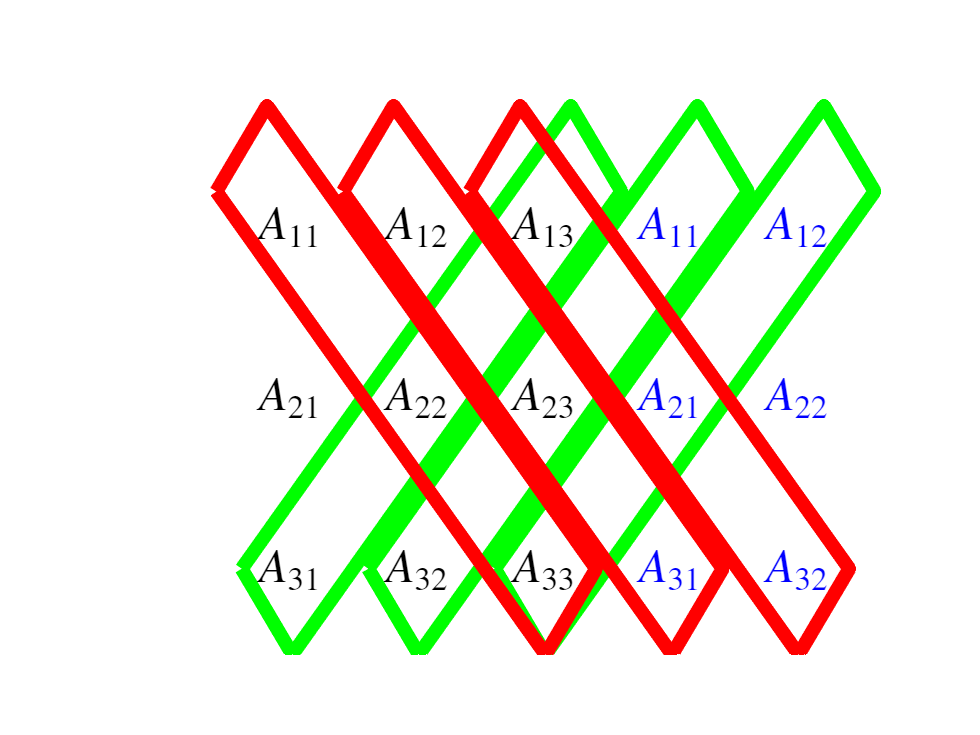

figII2_4()

N.B.   This mnemonic unfortunately **does not** generalize to the $4\times 4$ case in a way that would be easily useful.

Applying this mnemonic to obtain the characteristic polynomial of a $3\times 3$ matrix

        (II.3.10a)        $p_A(\lambda)=|A-\lambda I |=\left| \matrix{
A_{11}-\lambda & A_{12} & A_{13} \cr
A_{21} & A_{22}-\lambda & A_{23} \cr
A_{31} & A_{32} & A_{33}-\lambda }
\right|~=~$

    
$$-\lambda^3+(A_{11}+A_{22}+A_{33})\lambda^2-(A_{11}A_{22}-A_{12}A_{21}+A_{11}A_{33}-A_{13}A_{31}+A_{22}A_{33}-A_{23}A_{32})\lambda~+~$$


    
$$(A_{11}A_{22}A_{33}+A_{12}A_{23}A_{31}+A_{13}A_{21}A_{32}-A_{11}A_{23}A_{32}-A_{12}A_{21}A_{33}-A_{12}A_{22}A_{31})$$


This calculation is of course a bit cumbersome, but it contains mostly expected terms:    The coefficient of $\lambda^2$ is the trace of the matrix and the constant term is the determinant.   The coefficient of $\lambda$ is something new, but we can easily see that 

$A_{11}A_{22}-A_{12}A_{21}+A_{11}A_{33}-A_{13}A_{31}+A_{22}A_{33}-A_{23}A_{32}=
\left|\matrix{A_{11} & A_{12} \cr A_{21} & A_{22}}\right|+
\left|\matrix{A_{11} & A_{13} \cr A_{31} & A_{33}}\right|+
\left|\matrix{A_{22} & A_{23} \cr A_{32} &A_{33}}\right|$.

That is, the coefficient is the negative of the sum of the minors of the diagonal elements of the matrix (trace if the minor matrix).    Hence, the characteristic polynomial of a $3\times 3$ matrix $A$ is given by 

        (II.3.10b)        $p_A(\lambda)~=~ -\lambda^3 ~+~ \text{tr}(A) \lambda^2~-~\left(\left|\matrix{A_{11} & A_{12} \cr A_{21} & A_{22}}\right|+
\left|\matrix{A_{11} & A_{13} \cr A_{31} & A_{33}}\right|+
\left|\matrix{A_{22} & A_{23} \cr A_{32} &A_{33}}\right|\right)\lambda ~+~\det(A)$.

With appropriate care, the characteristic polynomial can be readily found once the determinant is known.   

**Examples II.3.1a**

        
$$\matrix{\bullet\cr 4\cr 7}~\left[\matrix{ 1 & 2 & 3 \cr 4 & 5 & 6\cr 7 & 8 & 9}\right]\sim
\matrix{\quad\cr\bullet\cr2}~\left[\matrix{1&2&3\cr 0 & -3 & -6\cr0 & -6 &-12}\right]\sim
\left[\matrix{1 & 2 & 3\cr 0 & -3 & -6 \cr 0 & 0 & 0}\right]\quad\Rightarrow\quad |A|=1(-3)0=0$$


    
$$p_A(\lambda)~=~ -\lambda^3 +(1+5+9)\lambda^2-\big( (5-8)+(9-21)+(45-48)\big)\lambda~-~0\qquad\Rightarrow$$
 

    
$$p_A(\lambda)~=~ -\lambda^3 +15\lambda^2+18\lambda$$


**Examples II.3.1b**

        
$$\matrix{\bullet\cr 2\cr 3}~\left[\matrix{1 & 2 & 3\cr 2 & 3 & 1 \cr 3 & 1 & 2}\right]\sim
\matrix{\quad\cr\bullet\cr 5}
\left[\matrix{1 & 2  & 3 \cr 0 & -1 & -5\cr 0 & -5 & -7}\right]\sim
\left[\matrix{1&2&3\cr 0 & -1 & -5\cr 0 & 0 &18}\right]\quad\Rightarrow\quad |A|=1(-1)18=-18$$


    
$$p_A(\lambda)~=~-\lambda^3~+~(1+3+2)\lambda^2~-~\big((3-4)+(2-9)+(6-1)\big)\lambda+(-18)$$


    
$$p_A(\lambda)~=~-\lambda^3~+~6\lambda^2+3\lambda-18$$


**Examples II.3.1c**

        
$$\matrix{\bullet\cr 2\cr 2}~\left[\matrix{1 & -2 & 2\cr 2 & -1 & -2 \cr 2 & 2 & 1}\right]\sim
\matrix{\quad\cr\bullet\cr 2}
\left[\matrix{1 & -2  & 2 \cr 0 & 3 & -6\cr 0 & 6 & -3}\right]\sim
\left[\matrix{1 & -2  & 2 \cr 0 & 3 & -6\cr 0 & 0 &9}\right]\quad\Rightarrow\quad |A|=1(3)9=27$$


    
$$p_A(\lambda)~=~-\lambda^3~+~(1-1+1)\lambda^2~-~\big((-1+4)+(1-4)+(-1+4)\big)\lambda+27$$


    
$$p_A(\lambda)~=~-\lambda^3~+~\lambda^2-3\lambda+27$$


Once the characteristic polynomial is found, the main consideration is generally finding its roots (i.e., the eigenvalues of the matrix).  For the $2\times 2$ case, this can be accomplished with the quadratic formula (among other ways).   For the $3\times 3 $ case, [the cubic formula](https://math.vanderbilt.edu/schectex/courses/cubic/), formula for the roots of a cubic polynomial, can do the trick.    This formula, however, is of such complexity as to be impractical for day-to-day use (including on exams).    Hence, we are generally reduced to the less systematic approach of obtaining one root by hook or by crook (actually "by crook" is not allowed on exams) and then using that root to factor out a linear factor from the characteristic polynomial leaving us to factor a relatively tractable quadratic polynomial.    Because this process can be useful in various applications (particularly those involving the Laplace transform) we review it in greater details below.

**Sometimes practical approaches to the roots of cubic polynomials.  **

**Example II.3.2a:**  Consider the cubic polynomial $p(\lambda)=-\lambda^3+\pi\lambda^2-2\lambda+2\pi$.   With astute powers of observation or a bit of luck, you will notice that $p(\pi)=0
$; that is, $\pi$ is a root of $p(\lambda)$.   With this knowledge, we can factor out $\lambda-\pi$ from $p(\lambda)$ which we can implement as either long polynomial division or as synthetic division:

long division:        $\matrix{
\quad & \quad &\ -\lambda^2 & &-2 & \cr
\hline\lambda-\pi &\bigg)&-\lambda^3 &+\pi\lambda^2&-2\lambda&2\pi\cr
\quad&\quad&-\lambda^3&+\pi\lambda^2\cr
\hline\quad&\quad&\quad&0&-2\lambda&+2\pi\cr
\quad&\quad&\quad&\quad&-2\lambda&+2\pi\cr
\hline\quad&\quad&\quad&\quad&\quad&0\cr
}$              synthetic division:        $\matrix{\underline{\pi}|&-1 & \pi & -2 & 2\pi\cr
\quad &\quad&-\pi&0&-2\pi\cr
\hline\qquad&-1 & 0 & -2 & 0\cr
\cr\cr\cr\cr
}$  

Hence, $p(\lambda)=(\lambda-\pi)(-\lambda^2-2)=-(\lambda-\pi)(\lambda^2+2)$.   The quadratic factor is easily further factored giving $p(\lambda)=-(\lambda-\pi)(\lambda-i\sqrt{2})(\lambda+i\sqrt{2})$ and the roots of the polynomial are $\{\pi,~i\sqrt{2},~-i\sqrt{2}\}$.

In the previous example, we relied on our powers of observation to find one root.    In the common case that the coefficients of the polynomial are integers then there are a limited number of possibilities for rational roots of the polynomial.   Each rational root must be a quotient of an integer factor of the constant term and an integer factor of the coefficient of the highest degree term.  Searching for a rational root is often fruitful (especially on exams).   

**Example II.3.2b:**  Consider the cubic polynomial $p(\lambda)=-6\lambda^3-5\lambda^2-47\lambda+8$ which has all integer coefficients.   The integer factors of 8 are $\pm 1, \pm2,\pm4,\pm8$(we must include negative factors) and the integer factors of -6 are $\pm 1, \pm 2, \pm 3, \pm 6$.    Hence, the candidates for rational roots of $p(\lambda)$ are 

$\left\{\pm\frac{1}{1},\pm\frac{1}{2},\pm\frac{1}{3},\pm\frac{1}{6},
\pm\frac{2}{1},\pm\frac{2}{2},\pm\frac{2}{3},\pm\frac{2}{6},
\pm\frac{4}{1},\pm\frac{4}{2},\pm\frac{4}{3},\pm\frac{4}{6},
\pm\frac{8}{1},\pm\frac{8}{2},\pm\frac{8}{3},\pm\frac{8}{6}\right\}~=~\left\{
\pm\frac16,\pm\frac13,\pm\frac12,\pm\frac23,\pm1,\pm\frac43,\pm2,\pm\frac83\pm4,\pm8\right\}$.

Searching through these candidates reveals that $p(1/6)=0$.   Hence, we can factor the polynomial.

long division:        $\matrix{
\quad & \quad &\ -\lambda^2 & -\lambda&-8 & \cr
\hline6\lambda-1 &\bigg)&-6\lambda^3 &-5\lambda^2&-47\lambda&+8\cr
\quad&\quad&-6\lambda^3&+\lambda^2\cr
\hline\quad&\quad&\quad&-6\lambda^2&-47\lambda&\cr
\quad&\quad&\quad&-6\lambda^2&+\lambda&\cr
\hline\quad&\quad&\quad&\quad&-48\lambda&+8\cr
\quad&\quad&\quad&\quad&-48\lambda&+8\cr
\hline\quad&\quad&\quad&\quad&\qquad&~~0\cr
}$              synthetic division:        $\matrix{\underline{\frac16}\bigg|&-6 & -5 & -47 & 8\cr
\quad &\quad&-1&-1&-8\cr
\hline\qquad&-6 & -6 & -48 & 0\cr
\cr\cr\cr\cr\cr\cr
}$  

Hence, $p(\lambda)=(6\lambda-1)(-\lambda^2-\lambda-8)=-(6\lambda-1)(\lambda^2+\lambda+8)=-(6\lambda-1)\left(\lambda-\frac{-1+i\sqrt{31}}{2}\right)\left(\lambda-\frac{-1-i\sqrt{31}}{2}\right)$and the roots are $\left\{\frac16,\frac{-1+i\sqrt{31}}{2},\frac{-1-i\sqrt{31}}{2}\right\}$.

Happily, in many applications (and hopefully on exams), the list of candidate roots is less extensive.

**Example II.3.2c:**  Consider the cubic polynomial $p(\lambda)=\lambda^3-6\lambda^2+11\lambda-6$  for which the candidate roots are $\{\pm1, \pm2, \pm3, \pm6\}$.   We quickly find $p(1)=0$.

long division:        $\matrix{
\quad & \quad &\ \lambda^2 & -5\lambda&+6 & \cr
\hline\lambda-1 &\bigg)&\lambda^3 &-6\lambda^2&+11\lambda&-6\cr
\quad&\quad&\lambda^3&-\lambda^2\cr
\hline\quad&\quad&\quad&-5\lambda^2&+11\lambda&\cr
\quad&\quad&\quad&-5\lambda^2&+5\lambda&\cr
\hline\quad&\quad&\quad&\quad&6\lambda&-6\cr
\quad&\quad&\quad&\quad&+6\lambda&-6\cr
\hline\quad&\quad&\quad&\quad&\qquad&~~0\cr
}$              synthetic division:        $\matrix{\underline{1}\bigg|&1 & -6 & 11 & -6\cr
\quad &\quad&1&-5&6\cr
\hline\qquad&1 & -5 & 6 & 0\cr
\cr\cr\cr\cr\cr\cr
}$  

Hence, $p(\lambda)=(\lambda-1)(\lambda^2-5\lambda+6)=(\lambda-1)(\lambda-2)(\lambda-3)$ and the roots are $\{1,2,3\}$.

Unfortunately, while we are guaranteed that every rational root has a very specific form, integer coefficients do not guarantee a rational root.    

A=[0 1 0; 0 0 1; 6 6 0]

A =      0     1     0
     0     0     1
     6     6     0


charpoly(A,x)

$$ans = x^{3}-6\,x-6$$

eig(sym(A))

$$ans = \begin{array}{l} \left(\begin{array}{c} 4^{1/3}+\frac{4^{2/3}}{2}\\ -\frac{4^{1/3}}{2}-\frac{4^{2/3}}{4}-\sigma_{1}\\ -\frac{4^{1/3}}{2}-\frac{4^{2/3}}{4}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(4^{1/3}-\frac{4^{2/3}}{2}\right)\,\mathrm{i}}{2} \end{array}$$

**Examples of eigenvalues of **$3\times 3$**matrices.   **Here the eigenvalues of the matrices found in Examples II.3.1abc are computed.

**Examples II.3.3a**


$$A=\left[\matrix{1&2&3\cr4&5&6\cr7&8&9}\right]\quad\Rightarrow\quad p_A(\lambda)=-\lambda^3+15\lambda^2+18\lambda~=~-\lambda (\lambda^2-15\lambda-18)\quad\qquad
\frac{15\pm\sqrt{15^2-4(-18)}}{2}=\frac{15\pm\sqrt{297}}{2}=\frac{15\pm3\sqrt{33}}{2}$$



$$\sigma(A)=\left\{0,\frac{15+3\sqrt{33}}{2},\frac{15-3\sqrt{33}}{2}\right\}$$


eig(sym([1 2 3; 4 5 6; 7 8 9]))'     % easy to check with MATLAB

$$ans = \left(\begin{array}{ccc} 0 & \frac{15}{2}-\frac{3\,\sqrt{33}}{2} & \frac{3\,\sqrt{33}}{2}+\frac{15}{2} \end{array}\right)$$

**Examples II.3.3b**

$A=\left[\matrix{1&2&3\cr 2&3 &1\cr 3&1&2}\right]
\quad\Rightarrow\quad p_A(\lambda)~=~-\lambda^3~+~6\lambda^2+3\lambda-18$      Guesses:  $\pm1, \pm2, \pm3, \pm6, \pm 9, \pm 18$  and eventually we find $p_A(6)=-6^3+6(6^2)+3(6)-18=0$.

        $\matrix{\underline{6}\bigg| & -1 & ~6 &3&-18\cr
&&-6 & 0&~18\cr
\hline&-1&~0&3&~~0\cr
}$        So, $p_A(\lambda)=-(\lambda-6)(\lambda^2-3)$ and $\sigma(A)=\left\{6,\sqrt{3},-\sqrt{3}\right\}$.

eig(sym([1 2 3; 2 3 1; 3 1 2]))'

$$ans = \left(\begin{array}{ccc} 6 & \sqrt{3} & -\sqrt{3} \end{array}\right)$$

**Example II.3.3c**

$A=\left[\matrix{1 & -2 &2\cr 2 & -1 & -2\cr 2 & 2 & -1}\right]\quad\Rightarrow\quad p_A(\lambda)=-\lambda^3+\lambda^2-3\lambda+27$        Guesses:  $\pm1,\pm3,\pm9,\pm18$ and $p_A(3)=-3^3+3^2-3(3)+27=0$.

        $\matrix{\underline{3}\bigg| & -1 & ~1 &-3& ~27\cr
&&-3 & -6&-27\cr
\hline&-1&-2&-9&~~0\cr
}$        So, $p_A(\lambda)=-(\lambda-3)(\lambda^2+2\lambda+9)$,  $\frac{-2\pm\sqrt{2^2-4\cdot 9}}{2}=\frac{-2\pm\sqrt{-32}}{2}=-1\pm2\sqrt{2} i$ and

        
$$\sigma(A)=\{3,-1+2\sqrt{2} i, -1-2\sqrt{2} i\}$$


eig(sym([1 -2 2; 2 -1 -2; 2 2 1]))'

$$ans = \left(\begin{array}{ccc} 3 & -1+2\,\sqrt{2}\,\mathrm{i} & -1-2\,\sqrt{2}\,\mathrm{i} \end{array}\right)$$

**Beyond **$3\times 3$.   While most of the formulas and ideas discussed above can be extended to larger matrices, the time and effort needed to apply them is generally extensive.    Many scientists of earlier generations have had the experience of spending a few weeks working out the eigenvalues of a larger, perhaps $6\times6$, matrix of particular significance in an important application.   These days software such as MATLAB can often save considerable amounts of time in such situations.    Nonetheless, software may well require human hints about the structure of the problem.    Perhaps, artificial intelligence will relieve future scientists of this burden altogether.

Matrices of special structure can nonetheless be tractable (even easy) despite their size.    Suppose that $A$ is a $6\times 6$ upper unitriangular matrix then

$p_A(\lambda)=|A-\lambda I|=\left|\matrix{1-\lambda & * & * & * & * & *\cr
0& 1-\lambda &  *&*&*&*\cr
0&0&1-\lambda&*&*&* \cr
0&0&0&1-\lambda&*&*\cr
0&0&0&0&1-\lambda&*\cr
0&0&0&0&0&1-\lambda\cr
}\right|~=~(1-\lambda)^6$.

The result is very simple as the determinant of a triangular matrix is just the product of the elements on its main diagonal.    It is evident that the one eigenvalue of $A$ is 1 and that it has multiplicity 6.     It is important to note that sometimes the computation of the characteristic polynomial produces a factored or partially factored form.   Since factorization is normally the ultimate goal, there is no need to multiply out such intermediate results unless the problem somehow explicitly requires it.    This result generalized to any triangular matrix, upper, lower or both (i.e., diagonal); specifically, such a matrix displays it eigenvalues directly on its main diagonal.   Hence, the characteristic polynomial of an $n\times n$ triangular matrix $A
$ is

        (II.3.11)        $p_A(\lambda)=\prod_{\ell=1}^n (A_{\ell\ell}-\lambda)$.

Later, we will see 

- the eigenvalues of a projection matrix must be either 1 or 0 (the numbers that are their own square roots),

- the eigenvalues of an orthogonal (or unitary) matrix must have an absolute value (modulus) of 1 (i.e., $\cos\theta+i\sin\theta$),

- an $n\times n$ real matrix with $n$ odd (e.g., $n=3$) must have at least one real eigenvalue.

**Putting eigenvalues and eigenvectors to work for 2x2 matrices:   diagonalization.**    A central objective of finding the eigenvalues and eigenvectors of a square matrix is to find an important factorization of the matrix known as ***diagonalization***.    A diagonalization of an $n\times n$ matrix $A$ consists of a nonsingular matrix $S$ and a diagonal matrix $D$ such that

        (II.3.12)        $A=SDS^{-1}$.

For a $2\times 2$ matrix $A=\left[\matrix{a&b\cr c&d}\right]$, diagonalization is fairly straightforward.    

1)  Find the eigenvalues, $\lambda_1$ and $\lambda_2$, of the matrix.   Equation (II.3.3) using the quadratic formula is often the way to get these.

2)  Solve $(A-\lambda_1 I){\bf x}_1={\bf 0}$ and $(A-\lambda_2 I){\bf x}_2={\bf 0}$ for ${\bf x}_1\ne {\bf 0}$ and ${\bf x}_2\ne{\bf 0}$ pointing in distinct directions.   Solving $(A-\lambda I){\bf x}={\bf 0}$ is very easy for $2\times 2$ matrices:

                    $A-\lambda I = \left[\matrix{u&v\cr w&y}\right] \qquad\Rightarrow\qquad (A-\lambda){\bf x}={\bf 0}$        when        ${\bf x}=\left[\matrix{-v \cr u}\right]$    or    ${\bf x}=\left[\matrix{-w \cr y}\right]$.

That is, there are generally two possible choices for the eigenvectors.   Of course, the eigenvector must be nonzero, so we must select the nonzero vector if one of them is zero.   If both are zero, then there are in fact two distinct eigenvectors including the pair

                    ${\bf x}_1=\left[\matrix{1\cr 0}\right]$    and    ${\bf x}_2=\left[\matrix{0\cr 1}\right]$.

3)  The eigenvectors, ${\bf x}_1$ and ${\bf x}_2$, are the columns of the nonsingular matrix $S$, and the eigenvalues, $\lambda_1$ and $\lambda_2$, are the diagonal entries of the diagonal matrix $D$.

        (II.3.13)        $S=\left[\matrix{{\bf x}_1 & {\bf x}_2}\right]$        and        $D=\left[\matrix{\lambda_1 & 0\cr 0 & \lambda_2}\right]$.

Focusing on real matrices, this procedures works out in slightly different ways depending on the sign of the discriminant $\text{tr}^2(A)-4\text{det}(A)$:

For $\text{tr}^2(A)-4\text{det}(A)>0$, two distinct real eigenvalues are obtained, two eigenvectors pointing in different directs and having real components may be obtained.

**Example II.3.1:   **Diagonalization of $A=\left[\matrix{5 & -6\cr 3 & -4}\right]$:

        $p_{A}(\lambda)=\lambda^2-\lambda-2$,        $\lambda=\frac{1\pm\sqrt{1+4\cdot 2}}{2}$,        $\lambda_1=2$    and    $\lambda_2=-1$.

        $A-\lambda_1I=\left[\matrix{3 & -6\cr 3 & -6}\right]$;        hence,    ${\bf x}_1=\left[\matrix{6\cr 3}\right]$.

        $A-\lambda_2I=\left[\matrix{6 & -6\cr 3 & -3}\right]$;        hence,    ${\bf x}_2=\left[\matrix{6\cr -6}\right]$.

        $S=\left[\matrix{6 & 6 \cr 3 & -6}\right]$    and    $D=\left[\matrix{2 & 0 \cr 0 & -1}\right]$. 

For $\text{tr}^2(A)-4\text{det}(A)=0$, the spectrum has only one value, and the eigenvalue has multiplicity 2 (i.e., $\lambda_1=\lambda_2$).   In this case, finding two eigenvectors with different directions is not guaranteed.

**Example II.3.2:   **Diagonalization of $A=\left[\matrix{5 & 0\cr 0 & 5}\right]$:

        $p_{A}(\lambda)=\lambda^2-10\lambda+25$,        $\lambda=\frac{5\pm\sqrt{100-4\cdot 25}}{2}$,        $\lambda_1=5$    and    $\lambda_2=5$.

        $A-\lambda_1I=\left[\matrix{0 & 0\cr 0 & 0}\right]$;        hence,    ${\bf x}_1=\left[\matrix{1\cr 0}\right]$    and   ${\bf x}_2=\left[\matrix{0\cr 1}\right]$ .

        $S=\left[\matrix{1 & 0 \cr 0 & 1}\right]$    and    $D=\left[\matrix{5 & 0 \cr 0 & 5}\right]$. 

**Example II.3.3:   **Diagonalization of $A=\left[\matrix{5 & 1\cr 0 & 5}\right]$:

        $p_{A}(\lambda)=\lambda^2-10\lambda+25$,        $\lambda=\frac{5\pm\sqrt{100-4\cdot 25}}{2}$,        $\lambda_1=5$    and    $\lambda_2=5$.

        $A-\lambda_1I=\left[\matrix{0 & 1\cr 0 & 0}\right]$;        hence,    ${\bf x}_1=\left[\matrix{1\cr 0}\right]$    but no eigenvector in any other direction.

 As a matrix with no diagonalization, this matrix is called ***defective.***

For $\text{tr}^2(A)-4\text{det}(A)<0$, there are two distinct eigenvalues which are complex conjugates of one another.   The two eigenvectors also may be chosen to be complex conjugates on each other.

**Example II.3.4:   **Diagonalization of $A=\left[\matrix{1 & 2\cr -2 & 1}\right]$:

        $p_{A}(\lambda)=\lambda^2-2\lambda+5$,        $\lambda=\frac{2\pm\sqrt{4-4\cdot 5}}{2}$,        $\lambda_1=1+2i$    and    $\lambda_2=1-2i$.

        $A-\lambda_1I=\left[\matrix{-2i & 2\cr -2 & -2i}\right]$;        hence,    ${\bf x}_1=\left[\matrix{-2\cr -2i}\right]$    and    ${\bf x}_2=\left[\matrix{-2\cr 2i}\right]$.

        $S=\left[\matrix{-2 & -2 \cr -2i & 2i}\right]$    and    $D=\left[\matrix{1+2i & 0 \cr 0 & 1-2i}\right]$. 

**Follow Up Problems:**

**Problem II.3.1:**   How is the quadratic formula derived?    

**Problem II.3.2:   **Find the characteristic polynomial and the eigenvalues for each of the following matrices.


$$\text{(a)}\quad \left[\matrix{a & b\cr b & a}\right]\qquad
\text{(b)}\quad \left[\matrix{a & b\cr -b & a} \right] \qquad
\text{(c)}\quad \left[\matrix{a&c\cr 0 & b}\right]\qquad
\text{(d)}\quad \left[\matrix{a & \pi & \sqrt{2} & 1+\sqrt{5}\cr
0 & b & \pi^2 & 1+i\cr
0 & 0 & c & \pi^3\cr
0 & 0 & 0 & d 
}\right]$$


**Problem II.3.3:   **Verify (II.3.6), $p_A(\lambda)~=~(\lambda-\lambda_1)(\lambda-\lambda_2)~=~\lambda^2-(\lambda_1+\lambda_2)\lambda~+~\lambda_1\lambda_2$, for the examples found in (II.3.4).   

**Problem II.3.4:   **For each of the following matrices, (a) find the characteristic polynomial, (b) find the eigenvalues, (c) verify the Cayley-Hamilton Theorem.


$$\text{(i)}\quad\left[\matrix{1 & 0 \cr 0 & 1}\right]\qquad
\text{(ii)}\quad\left[\matrix{1 & 2 \cr 0 & 3}\right]\qquad
\text{(iii)}\quad\left[\matrix{1 & i \cr 0 & 3}\right]\qquad
\text{(iv)}\quad\left[\matrix{0 & 0 \cr 0 & 0}\right]\qquad
\text{(v)}\quad\left[\matrix{0 & 4 \cr 0 & 0}\right]\qquad
\text{(vi)}\quad\left[\matrix{1 & i \cr -i & 2}\right]$$


**Problem II.3.5:   **Verify (II.3.8).

**Problem II.3.6:  **For each of the following matrices, (a) find the characteristic polynomial, (b) find the eigenvalues, (c) verify the Cayley-Hamilton Theorem.


$$\text{(i)}\quad\left[\matrix{1 &a & b \cr 0 & 1 & c\cr 0 & 0 & 1}\right]\qquad
\text{(ii)}\quad\left[\matrix{1 & 2 & 3\cr 4&5&6\cr 7&8&9}\right]\qquad
\text{(iii)}\quad\left[\matrix{0 & 0 & 0\cr 0 & 0 & 0 \cr 0&0&0}\right]\qquad
\text{(iv)}\quad\left[\matrix{2 & 1 &0\cr 1&2&1\cr 0 & 1 & 2}\right]$$


**Problem II.3.7:  **For a general $3\times 3$matrix $A,$find (a)  $p_A(0)$, (b) $p'_A(0)$, (c) $p''_A(0)$,  (d) $p'''_A(0)$ and (e) $p''''_A(0)$. 

**Problem II.3.8:  **Find the eigenvalues of $A=\left[\matrix{1 & 0 & 0 & 0 &0 & 0\cr 2 &\pi & 0 &0 &0&0\cr
3 & \sqrt{2} & \pi^2 & 0 & 0 & 0 \cr 
4 & \sqrt{2} & e^2 & \pi^3 &0&0\cr
5 & \sqrt{3} & \sqrt{1+e^2} & \sin(\pi/47)& \pi^4 &0\cr
6 &\sqrt{5} & \sqrt{2+e^2} &\sin(\pi/97) & \cosh(99) & \pi^5
}\right]$.

**Problem II.3.9:   **Show that if $A=\left[\matrix{a & b & e & f \cr c&d&g&h \cr 0 &0&x&y\cr 0 &0&z&w}\right]$ then $p_A(\lambda)=\left|\matrix{a-\lambda & b\cr c&d-\lambda}\right|\,
\left|\matrix{x-\lambda & y\cr z&w-\lambda}\right|$.

**Problem II.3.10:   **Find the eigenvalues of the rank 1 orthogonal projection matrix $P=\left[\matrix{\cos^2\theta &\cos\theta\sin\theta\cr \cos\theta\sin\theta & \sin^2\theta}\right]$.

**Problem II.3.11:  **Suppose $ac+bd=1$.  Find the eigenvalues of the rank 1 matrix projection matrix $P=\left[\matrix{a\cr b}\right]\left[\matrix{c & d}\right].$

**Problem II.3.12:   **Find the eigenvalues of $\text{Rot}(\theta)=\left[\matrix{\cos\theta & -\sin\theta\cr \sin\theta & \cos\theta}\right].$

**Problem II.3.13:   **Find the eigenvalues of $\text{Ref}(\theta)=\left[\matrix{\cos2\theta & \sin2\theta \cr \sin2\theta & - \cos2\theta}\right]$.

**Problem II.3.14:   **Why must a $3\times 3$ real matrix have at least one real eigenvalue?

**Problem II.3.15:   **Find, if possible, the diagonalization of each of the following matrices:

    (a)    $\left[ \matrix{1 & 1 \cr 1 & 1} \right]$        (b)    $\left[\matrix{1 & -1 \cr 1 & 1 }\right]$        (c)    $\left[\matrix{0 & 4 \cr -1 & 4}\right]$        (d)    $\left[\matrix{0 & 0 \cr 0 & 0 }\right]$

function figII2_4()
axis([0 6 -3.5 0])
axis off
text(1,-1,"$A_{11}$",'Interpreter','latex','FontSize',20,'Color','k')
text(2,-1,"$A_{12}$",'Interpreter','latex','FontSize',20,'Color','k')
text(3,-1,"$A_{13}$",'Interpreter','latex','FontSize',20,'Color','k')
text(4,-1,"$A_{11}$",'Interpreter','latex','FontSize',20,'Color','b')
text(5,-1,"$A_{12}$",'Interpreter','latex','FontSize',20,'Color','b')
text(1,-2,"$A_{21}$",'Interpreter','latex','FontSize',20,'Color','k')
text(2,-2,"$A_{22}$",'Interpreter','latex','FontSize',20,'Color','k')
text(3,-2,"$A_{23}$",'Interpreter','latex','FontSize',20,'Color','k')
text(4,-2,"$A_{21}$",'Interpreter','latex','FontSize',20,'Color','b')
text(5,-2,"$A_{22}$",'Interpreter','latex','FontSize',20,'Color','b')
text(1,-3,"$A_{31}$",'Interpreter','latex','FontSize',20,'Color','k')
text(2,-3,"$A_{32}$",'Interpreter','latex','FontSize',20,'Color','k')
text(3,-3,"$A_{33}$",'Interpreter','latex','FontSize',20,'Color','k')
text(4,-3,"$A_{31}$",'Interpreter','latex','FontSize',20,'Color','b')
text(5,-3,"$A_{32}$",'Interpreter','latex','FontSize',20,'Color','b')
hold on
plot([ 0.9 1.3 3.9 3.5 0.9],[-3.0 -3.5 -0.8 -0.3 -3.0],'g','LineWidth',6)
plot([ 0.9 1.3 3.9 3.5 0.9]+1,[-3.0 -3.5 -0.8 -0.3 -3.0],'g','LineWidth',6)
plot([ 0.9 1.3 3.9 3.5 0.9]+2,[-3.0 -3.5 -0.8 -0.3 -3.0],'g','LineWidth',6)
plot([ 0.9 1.3 3.9 3.5 0.9]-0.2,[-0.8 -0.3 -3.0 -3.5 -0.8],'r','LineWidth',6)
plot([ 0.9 1.3 3.9 3.5 0.9]+0.8,[-0.8 -0.3 -3.0 -3.5 -0.8],'r','LineWidth',6)
plot([ 0.9 1.3 3.9 3.5 0.9]+1.8,[-0.8 -0.3 -3.0 -3.5 -0.8],'r','LineWidth',6)
end